%% Section 1: CAN Network Node and Signal Parameters
clear; clc;

% Simulation Time Parameters
totalTime = 2.0;       % Total duration in seconds
timeStep = 0.01;       % 10ms network clock step
timeVector = 0:timeStep:totalTime;
numSteps = length(timeVector);

% Node 1: Powertrain Control Module (PCM) - ID: 0x100 (High Priority)
pcm_ID = '100'; 
engineRPM = 800 + 1500 * sin(2 * pi * 0.5 * timeVector) + 50 * randn(1, numSteps);

% Node 2: Battery Management System (BMS) - ID: 0x200 (Med Priority)
bms_ID = '200';
batterySoC = 85 - 0.1 * timeVector; % Gradually discharging

% Node 3: Dashboard Cluster (IPC) - ID: 0x300 (Low Priority)
ipc_ID = '300';
cabinTemp = 22 + 0.5 * log(timeVector + 1);

disp('Automotive Network Nodes and Signal Generation Initialized.');

Automotive Network Nodes and Signal Generation Initialized.



%% Section 2: Generating and Logging Network Traffic Stream
% Pre-allocating a structural array to look like a hardware packet analyzer log
canTrafficLog = struct('Timestamp', {}, 'ID', {}, 'DLC', {}, 'DataBytes', {});

logIdx = 1;
for i = 1:numSteps
    currTime = timeVector(i);

    % 1. Powertrain transmits every 10ms (Every step)
    canTrafficLog(logIdx).Timestamp = currTime;
    canTrafficLog(logIdx).ID = ['0x', pcm_ID];
    canTrafficLog(logIdx).DLC = 2;
    % Pack dynamic RPM data scaled into two fake payload bytes
    rpmValue = uint16(max(0, engineRPM(i)));
    canTrafficLog(logIdx).DataBytes = [bitand(rpmValue, 255), bitshift(rpmValue, -8)];
    logIdx = logIdx + 1;

    % 2. BMS transmits every 20ms
    if mod(i, 2) == 0
        canTrafficLog(logIdx).Timestamp = currTime;
        canTrafficLog(logIdx).ID = ['0x', bms_ID];
        canTrafficLog(logIdx).DLC = 1;
        canTrafficLog(logIdx).DataBytes = [uint8(batterySoC(i))];
        logIdx = logIdx + 1;
    end

    % 3. Dashboard transmits every 50ms
    if mod(i, 5) == 0
        canTrafficLog(logIdx).Timestamp = currTime;
        canTrafficLog(logIdx).ID = ['0x', ipc_ID];
        canTrafficLog(logIdx).DLC = 1;
        canTrafficLog(logIdx).DataBytes = [uint8(cabinTemp(i))];
        logIdx = logIdx + 1;
    end
end

% Convert to table layout for clean viewing in Live Script
trafficTable = struct2table(canTrafficLog);
disp('First 10 Rows of Captured Network Bus Traffic:');

First 10 Rows of Captured Network Bus Traffic:


head(trafficTable, 10)

    Timestamp       ID        DLC    DataBytes
    _________    _________    ___    _________

         0       {'0x100'}     2     {[ 59 3]}
      0.01       {'0x100'}     2     {[171 3]}
      0.01       {'0x200'}     1     {[   85]}
      0.02       {'0x100'}     2     {[ 13 3]}
      0.03       {'0x100'}     2     {[216 3]}
      0.03       {'0x200'}     1     {[   85]}
      0.04       {'0x100'}     2     {[236 3]}
      0.04       {'0x300'}     1     {[   22]}
      0.05       {'0x100'}     2     {[201 3]}
      0.05       {'0x200'}     1     {[   85]}



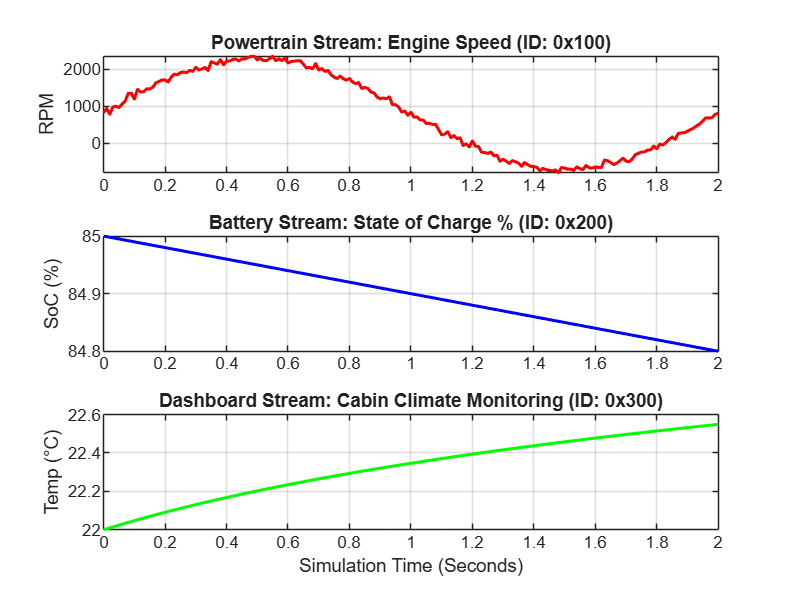


%% Section 3: In-Vehicle Telemetry Visualization
figure('Position', [100, 100, 800, 600]);

% Subplot 1: Powertrain Data
subplot(3,1,1);
plot(timeVector, engineRPM, 'r', 'LineWidth', 1.5);
title('Powertrain Stream: Engine Speed (ID: 0x100)');
ylabel('RPM'); grid on;

% Subplot 2: BMS Data
subplot(3,1,2);
plot(timeVector, batterySoC, 'b', 'LineWidth', 1.5);
title('Battery Stream: State of Charge % (ID: 0x200)');
ylabel('SoC (%)'); grid on;

% Subplot 3: Dashboard Data
subplot(3,1,3);
plot(timeVector, cabinTemp, 'g', 'LineWidth', 1.5);
title('Dashboard Stream: Cabin Climate Monitoring (ID: 0x300)');
xlabel('Simulation Time (Seconds)'); ylabel('Temp (°C)'); grid on;